Assignment type = **Individual**; Points = 12

**Due at the start of 4/12.**

**Problem 1 | Flowchart**

Given the flowchart shown (Figure 1), type up the appropriate code using proper MATLAB syntax to implement the algorithm.

**Figure 1**

*Flowchart for assignment.*

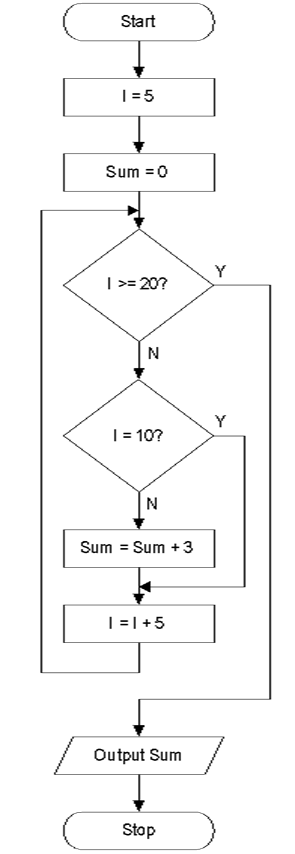

% ENSC192 - Spring 2023 - Section 02 - Gabe DiMartino
% Assignment: A5 Repetitive Structures P1
% Date: 04/17/2023
% Find: solution to flow chart
%------------- BEGIN CODE --------------
clear; clc;
I = 5;
Sum = 0;

while I < 20
    if I == 10
        I = I+5;
    else
        Sum = Sum +3;
        I = I+5;
    end
end

fprintf("Sum is equal to: %0.2f",Sum)

Sum is equal to: 6.00

%------------- END OF CODE --------------

**Problem 2 | Wind Chill Factor**

The wind chill factor (WCF) describes how cold it “feels” for a given temperature in Fahrenheit based upon actual temperature and wind speed (in miles per hour).  The equation for wind chill factor (WCF) is:

        WCF = 35.7 + 0.6 Temperature  – 35.7 (Wind Speed^0.16) + 0.43 Temperature (Wind Speed^0.16)

Compute and display the wind chill factor (WCF) using the given temperature, over the wind speed range in increments of 5 miles per hour.  For this example use a temperature of 10 degrees F, a minimum wind speed of 5 mph and a maximum wind speed of 20 mph. The output of the program should look exactly like this (that is, use ***fprintf*** to insert your calculated values rounded to the tenth place):

For a temperature of 10 degrees F

The wind chill factor for a wind speed of 5 m.p.h is: x.x degrees F

The wind chill factor for a wind speed of 10 m.p.h is: x.x degrees F

The wind chill factor for a wind speed of 15 m.p.h is: x.x degrees F

The wind chill factor for a wind speed of 20 m.p.h is: x.x degrees F

% ENSC192 - Spring 2023 - Section 02 - Gabe DiMartino
% Assignment: A5 Repetitive Structures P2
% Date: 04/17/2023
% Find: wind chill for a range of speeds
% Given: t, vMin, vMax
% Variables: v, wcf
%------------- BEGIN CODE --------------
t = 10;
vMin= 5;
vMax= 20;
%calculation
v=vMin:5:vMax;
wcf=35.7+0.6*t-35.7*(v.^0.16)+0.43*t*(v.^0.16);
%outputs
fprintf('For a temperature of %d degrees F\n',t);

For a temperature of 10 degrees F


for i=1:length(v)
    fprintf('\nThe wind chill factor for a wind of %d mph is %.2f degrees F\n',v(i),wcf(i));
end


The wind chill factor for a wind of 5 mph is 1.08 degrees F

The wind chill factor for a wind of 10 mph is -3.69 degrees F

The wind chill factor for a wind of 15 mph is -6.73 degrees F

The wind chill factor for a wind of 20 mph is -9.01 degrees F


%------------- END OF CODE --------------

**Problem 3 | Blood Pressure**

Write an algorithm that will determine a person’s blood pressure category.  The user will have to input his/her systolic and diastolic blood pressure readings - using the MATLAB function input(  ). The program should determine the user’s category as designated in the table below (Figure 2) and then output the statement **Your Blood Pressure Reading Indicates**: followed by the correct category. 

**Figure 2**

*Table of blood pressure categories for different systolic and diastolic readings.*

 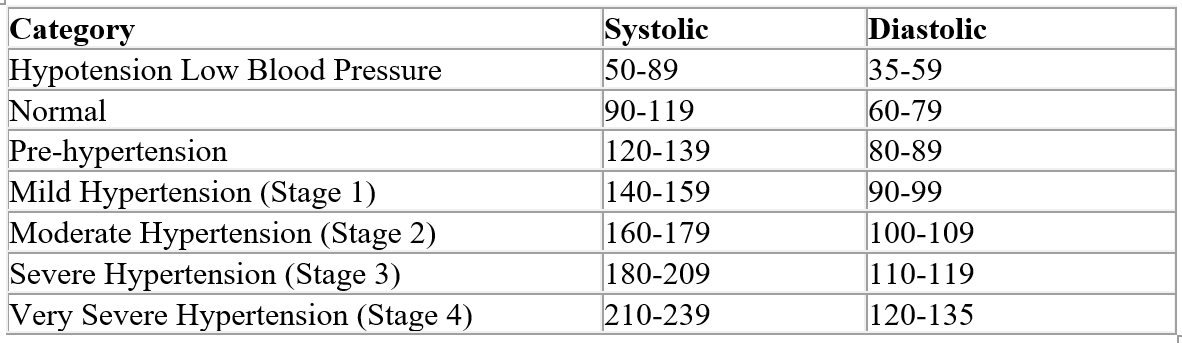

Other requirements for the program:

- Your program should first check for invalid readings and should output an error message. Systolic or diastolic readings that fall below or above the readings on the table indicate the user is either in a coma, in severe medical distress, or dead.

- If a person’s readings put them in two different categories, the higher category should be selected. For example, someone with a blood pressure reading of 118/85 would be categorized as normal for the systolic reading, and pre-hypertensive for the diastolic reading. The program should output pre-hypertension in this case.  However, if a person has one reading that is normal and one reading in hypotension (low), they should be categorized as hypotension (low blood pressure). Note that this a unique case and the logic should follow.

**Hint**: This is not as difficult as it first appears. Remember how the if-else construct works. You only get to an else statement when all the statements above it evaluates to false.

**Note: **Entire file should be less than 25 lines of code (not including header, whitespace, and comments).  If it is longer, you should really check your logic.

% ENSC192 - Spring 2023 - Section 02 - Gabe DiMartino
% Assignment: A5 Repetitive Structures P3
% Date: 04/17/2023
% Given: Input of blood Pressure from user
% Constants: threshold for each level of systolic/diatolic
% Variables: systolic, diatolic
%------------- BEGIN CODE --------------
systolic = input("Systolic Blood Pressure? : ");
diatolic = input("Diatolic Blood Pressure? : ");
if (systolic < 50 || systolic > 239) || (diatolic < 35 || diatolic > 135)
    fprintf("User is outside of the normal range, user is unalived or in a coma.\n")
elseif systolic >= 50 && systolic < 89 || (diatolic >= 35 && diatolic < 59)
    fprintf("User is in Hypotension Low Blood Pressure.\n")
elseif systolic >= 89 && systolic < 119 || (diatolic >= 59 && diatolic < 79)
    if (systolic > 119) || (diatolic > 79)
        fprintf("User is in Pre-Hypertension.\n")
    elseif (systolic < 89) || (diatolic < 59)
        fprintf("User is in Hypotension Low Blood Pressure.\n")
    else
        fprintf("User is in Normal Blood Pressure.\n")
    end
elseif (systolic >= 119 && systolic < 139) || (diatolic >= 79 && diatolic < 89)
    if (systolic > 139) || (diatolic > 89)
        fprintf("User is in Mild Hypertension (Stage 1).\n")
    else
        fprintf("User is in Pre-Hypertension.\n")
    end
    
elseif (systolic >= 139 && systolic < 159) || (diatolic >= 89 && diatolic < 99)
    if (systolic > 159) || (diatolic > 99)
        fprintf("User is in Moderate Hypertension (Stage 2).\n")
    else
        fprintf("User is in Mild Hypertension (Stage 1).\n")
    end

elseif (systolic >= 159 && systolic < 179) || (diatolic >= 99 && diatolic < 109)
    if (systolic > 179) || (diatolic > 109)
        fprintf("User is in Severe Hypertension (Stage 3).\n")
    else
        fprintf("User is in Moderate Hypertension (Stage 2).\n")
    end      
elseif (systolic >= 179 && systolic < 209) || (diatolic >= 109 && diatolic < 119)
    if (systolic > 209) || (diatolic > 119)
        fprintf("User is in Very Severe Hypertension (Stage 4).\n")
    else
        fprintf("User is in Severe Hypertension (Stage 3).\n")
    end            
elseif (systolic >= 209 && systolic < 239) || (diatolic >= 119 && diatolic < 135)
    fprintf("User is in Very Severe Hypertension (Stage 4).\n")
else
    disp("Invalid input, please input an Integer within the range")
end

User is in Pre-Hypertension.


%------------- END CODE --------------

**Problem 4 | Drag Coefficient**

The air resistance to motion of a vehicle (aka drag force) is determined experimentally by placing a car in a wind tunnel (wheeeeee). The air speed inside the tunnel is changed (to simulate different driving speeds) and the drag force acting on the car is measured.  The drag coefficient (Cd) represents this experimental data and is defined by the following relationship:

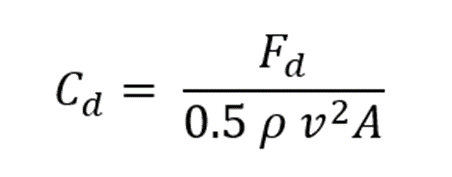

where

          Cd = drag coefficient (unitless)

          Fd = measured drag force (N)

              p  = air density (kg/m3)

          v  = air speed inside the wind tunnel (m/s)

          A = frontal area of the car (m2)

The frontal area A represents the frontal projection of the car’s area and can be approximated by multiplying 0.85 times the width and the height of a rectangle that outlines the front of a car.  This is the area that you see when you view the car from a direction normal to the front grill.  The 0.85 factor is used to adjust for rounded corners, open space below the bumper and so on. Typical drag coefficient values for sports cars are between 0.27 and 0.38 and for sedans are between 0.34 and 0.5.

The power requirement to overcome air resistance is computed by:

P = Fdv

where

              P   = power (KW) 

        and 1 horse power (hp) = .746 KW

Determine the power requirement to overcome the air resistance for a car that has a listed drag coefficient of 0.4 and width of 72.4 inches and a height of 56.4 inches.  Vary the air speed in the range of 10 m/s < V < 30 m/s and change temperature to range from 0 to 30 degrees C (both in increments of 5).  The relationship using the ideal gas law to temperature is: rho  = 0.35/T where the temperature is in Kelvin. This should be written as a nested for loop. The output should be a 2D array that you can format into a table.  Present two tabular findings for values in kilowatts  and horsepower. Make sure to have appropriate APA formatting.

**Hint**: It is best to create one “constant” from all the known variables to simplify the inputs within the *for *loop – make sure to check your units! Plus, this problem might be familiar to you...

% ENSC192 - Spring 2023 - Section 02 - Gabe DiMartino
% Assignment: A5 Repetitive Structures P4
% Date: 04/17/2023
% Find: Power in kW and HP
% Given: Speeds, Temperatures
% Variables: powerKW, speeds, temps, tempsK, powerHP

% ------------------ START CODE --------------------------
powerKW = zeros(5,7);
speeds = 10:5:30;
temps = 0:5:30;
tempsK = temps + 273.15;

% For loop for power (kW)
for i = 1:5
    for j = 1:7
        powerKW(i,j) = 0.1639340721*((speeds(i)^3)/tempsK(j));
    end
end

% Create the table for (kW), assign to tableKW
powerSpeed = [speeds',powerKW];
tableKW = table(powerSpeed(:,1), powerSpeed(:,2), powerSpeed(:,3), powerSpeed(:,4), ...
    powerSpeed(:,5), powerSpeed(:,6), powerSpeed(:,7), powerSpeed(:,8),'VariableNames',{'Air Speed' '0C' '5C' '10C' '15C' '20C' ...
    '25C' '30C'} );

% Convert power (kW) to power (HP)
powerHP = powerKW/0.746;

% Create the table for (HP), assign to tableHP
hpSpeed = [speeds',powerHP];
tableHP = table(hpSpeed(:,1), hpSpeed(:,2), hpSpeed(:,3), hpSpeed(:,4), ...
    hpSpeed(:,5), hpSpeed(:,6), hpSpeed(:,7), hpSpeed(:,8),'VariableNames',{'Air Speed' '0C' '5C' '10C' '15C' '20C' ...
    '25C' '30C'} );

% Display Tables
disp('Table 1. Power (kW) based on windspeed and temperature')

Table 1. Power (kW) based on windspeed and temperature


disp(tableKW)

    Air Speed      0C         5C         10C        15C        20C        25C        30C  
    _________    _______    _______    _______    _______    _______    _______    _______

       10        0.60016    0.58937    0.57897    0.56892    0.55922    0.54984    0.54077
       15         2.0255     1.9891      1.954     1.9201     1.8874     1.8557     1.8251
       20         4.8013      4.715     4.6317     4.5514     4.4737     4.3987     4.3262
       25         9.3775      9.209     9.0463     8.8894     8.7377     8.5912     8.4495
       30         16.204     15.913     15.632     15.361     15.099     14.846     14.601



disp('Table 2. Power (HP) based on windspeed and temperature')

Table 2. Power (HP) based on windspeed and temperature


disp(tableHP)

    Air Speed      0C         5C         10C        15C        20C        25C        30C  
    _________    _______    _______    _______    _______    _______    _______    _______

       10        0.80451    0.79004    0.77609    0.76263    0.74962    0.73705    0.72489
       15         2.7152     2.6664     2.6193     2.5739       2.53     2.4875     2.4465
       20          6.436     6.3204     6.2087      6.101      5.997     5.8964     5.7991
       25          12.57     12.344     12.126     11.916     11.713     11.516     11.326
       30         21.722     21.331     20.955     20.591      20.24       19.9     19.572



% ------------------ END CODE --------------------------